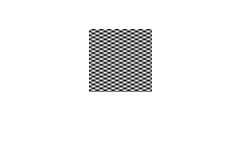

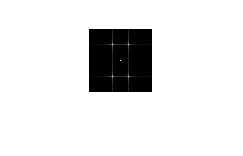

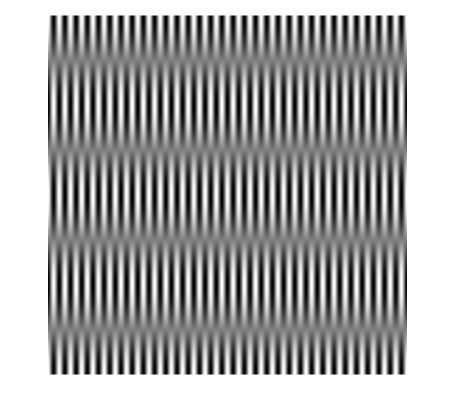

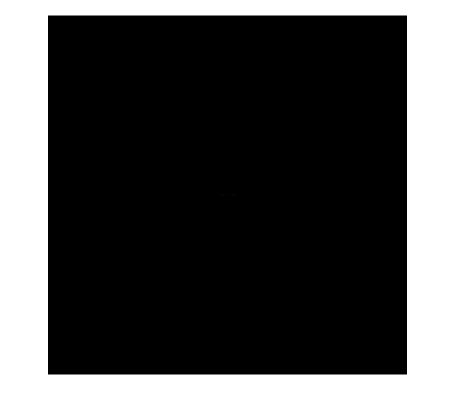

clc;clear all
i1 = 0:0.1:2*pi;
j1 = cos(4*i1);
i11 = repmat(j1,63,1);
j2 = cos(16*i1);
i22 = repmat(j2,63,1);
j22t = transpose(i22);
jj= (i11.*j22t+1)/2;
imshow(jj);
jjf = fftshift(fft2(jj));
fftshow(jjf,'log');
i2 = 0:0.1:64*pi;
j3 = cos(i2);
j33 = repmat(j3,2011,1);
j4 = cos(1/16*i2);
j4t = transpose(j4);
j44 = repmat(j4t,1,2011);
jj1 = (j33.*j44+1)/2;
imshow(jj1);
jj1f = fftshift(fft2(jj1));
fftshow(jj1f,'log');